Utilizando la aproximación de desacople cinemático, se realizan los siguiente esquemas para determinar la cinemática inversa de la posición.

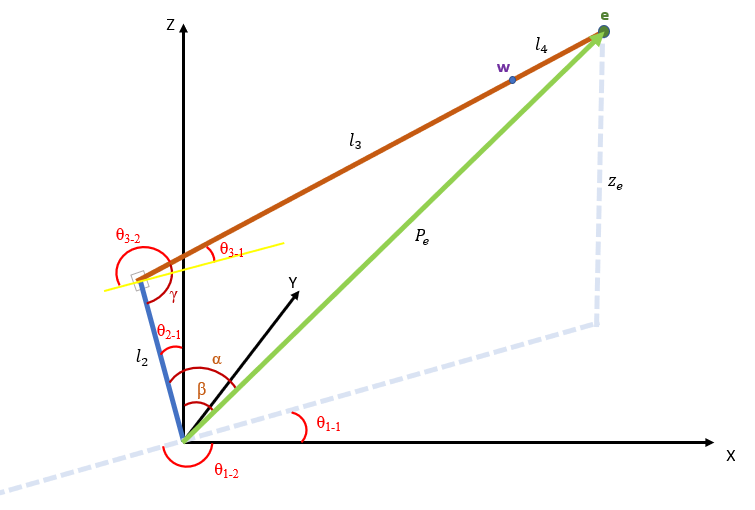

Se define el vector $e$ con las componentes correspondientes.


$$e=\left\lbrack \begin{array}{c}
x_e \\
y_e \\
z_e 
\end{array}\right\rbrack$$
 

A partir del plano X-Y se determinan las dos posibles soluciones para $\theta_1$.


$$$$\theta_{1-1} = atan2\left(\frac{y_e}{x_e}\right)$$

$$\theta_{1-2} = -\pi+atan2\left(\frac{y_e}{x_e}\right)$$$$


Con la magnitud del vector $e$ y el teroema del coseno se definen los ángulos $\alpha$ y $\beta \;$que determinanan las dos posibles solicuciones para $\theta_2$.


$$


$$P_e= \sqrt{x_e^2+y_e^2+z_e^2}$$$$



$$
(l_3+l_4)^2=L_2^2+P_e^2-2\cdot l_2\cdot P_e\cdot\cos(\alpha)\\

\cos(\alpha)=\frac{l_2^2+P_e^2-(l_3+l_4)^2}{2\cdot l_2\cdot P_e} \\

\alpha= \arccos\left(\frac{l_2^2+P_e^2-(l_3+l_4)^2}{2\cdot l_2\cdot P_e}\right)

$$



$$cos(\beta)=\frac{\sqrt{x_e^2+y_e^2}}{P_e}\\
\beta=arccos\left(\frac{\sqrt{x_e^2+y_e^2}}{P_e}\right)

$$



$$$$\theta_{2-1}= \alpha-\beta$$

$$\theta_{2-2}= \alpha+\beta$$$$
    

Nuevamente, a partir del vector $e$ y del teorema del coseno para el ángulo $\gamma$ se determinan las cuatro posibles soluciones para $\theta_3$.


$$P_e^2=l_2+(l_3+l_4)^2-2\cdot l_2\cdot (l_3+l_4) \cdot cos(\gamma)\\
cos(\gamma)=\frac{l_2+(l_3+l_4)^2-P_e^2}{2\cdot l_2\cdot (l_3+l_4)}\\
\gamma=arccos\left(\frac{l_2+(l_3+l_4)^2-P_e^2}{2\cdot l_2\cdot (l_3+l_4)}\right)$$



$$\theta_{3-1}=\pm \left(\gamma -\frac{\pi}2 \right)\\
\theta_{3-2}=\pm \left(\gamma -\frac{3\pi}2\right)$$


Conociendo que la orientación de la muñeca corresponde a la orientación de la base hasta el sistema coordenado 3 se puede expresar esta orientación de la siguiente forma:


$$O_w =\left\lbrack \begin{array}{ccc}
0 & -1 & 0\\
0 & 0 & -1\\
1 & 0 & 0
\end{array}\right\rbrack \cdot \;\textrm{Rot}\left(x,\theta_1 \right)\cdot \;\textrm{Rot}\left(y,\theta_2 +\theta_3 \right)$$


Por la configuración del robot se puede ver que el efector final cambia su orientación gracias a los ejes 4, 5 y 6 que se encuentran intersectados en el punto $w$ lo cual se puede expresar en rotaciones de Euler ZYZ para de este modo hallar el valor de $\theta_4$, $\theta_5$ y $\theta_6$


$$$$O_e=O_w\cdot Rot(z,\theta_4) \cdot Rot(y,\theta_5)\cdot Rot(z,\theta_6)$$

$$R=O_w^{-1}\cdot O_e = Rot(z,\theta_4) \cdot Rot(y,\theta_5)\cdot Rot(z,\theta_6)$$$$


Es evidente que la forma de la matriz anterior es:

syms theta4 theta5 theta6
R = rotz(theta4)*roty(theta5)*rotz(theta6)

$$R = \left(\begin{array}{ccc} \cos\left(\theta_{4}\right)\,\cos\left(\theta_{5}\right)\,\cos\left(\theta_{6}\right)-\sin\left(\theta_{4}\right)\,\sin\left(\theta_{6}\right) & -\cos\left(\theta_{6}\right)\,\sin\left(\theta_{4}\right)-\cos\left(\theta_{4}\right)\,\cos\left(\theta_{5}\right)\,\sin\left(\theta_{6}\right) & \cos\left(\theta_{4}\right)\,\sin\left(\theta_{5}\right)\\ \cos\left(\theta_{4}\right)\,\sin\left(\theta_{6}\right)+\cos\left(\theta_{5}\right)\,\cos\left(\theta_{6}\right)\,\sin\left(\theta_{4}\right) & \cos\left(\theta_{4}\right)\,\cos\left(\theta_{6}\right)-\cos\left(\theta_{5}\right)\,\sin\left(\theta_{4}\right)\,\sin\left(\theta_{6}\right) & \sin\left(\theta_{4}\right)\,\sin\left(\theta_{5}\right)\\ -\cos\left(\theta_{6}\right)\,\sin\left(\theta_{5}\right) & \sin\left(\theta_{5}\right)\,\sin\left(\theta_{6}\right) & \cos\left(\theta_{5}\right) \end{array}\right)$$

Despejando se encuentra que:


$$\theta_4 =\tan^{-1} \left(\frac{R_{2,3} }{R_{1,3} }\right)$$



$$\theta_5 =\cos^{-1} \left(R_{3,3} \right)$$



$$\theta_6 =\tan^{-1} \left(\frac{R_{3,2} }{-R_{3,1} }\right)$$


Considerando todas las posibles configuraciones que pueden resultar en la misma posición y orientación del efector final, se determinan **4 posibles soluciones**.

Peter Corke ofrece diferentes opciones para hallar la cinemática inversa:

- **ikine: **Cinemática inversa para robots de 6 o más grados de libertad con muñeca esférica. También puede ser usado para robots de 3 grados de libertad, pasando como parámetro una mascara con esta información. 

- **ikinei3: **Cinemática inversa para robots de 3 grados de libertad. Es la misma funcion **ikine6 **pero sin la muñeca.

- **ikine6s: **Cinemática inversa analítica para robots de 6 grados de libertad con muñeca esférica. Trata los siguientes casos específicos como el robot Kuka KR5 con muchas compensaciones (7 parámetros de longitud), Brazos Puma 560 con compensación de hombros y codos (4 parámetros de longitud) y Robot con un hombro desplazado y una tercera articulación prismática (como el brazo de Stanford). Además, los robots deben estar definidos usando DH estandar.

- **ikine_sym: **Devuelve la solucion simbólica en forma de cell array y muestras todas las posibles soluciones.

- **ikinem: **Inversa numérica por minimización que se encuentra en desarrollo. Devuleve la solución al llegar a un mínimo local.

En este caso  debido a que el LR Mate 200ib es un robot de 6 grados de libertad con muñeca esferica, pues 3 articulaciones intersectan sus ejes. se puede utilizar la función **ikine.**

Teniendo en cuenta las MTH calculadas para el “Modelo Geométrico Directo” para las 4 configuraciones del robot:

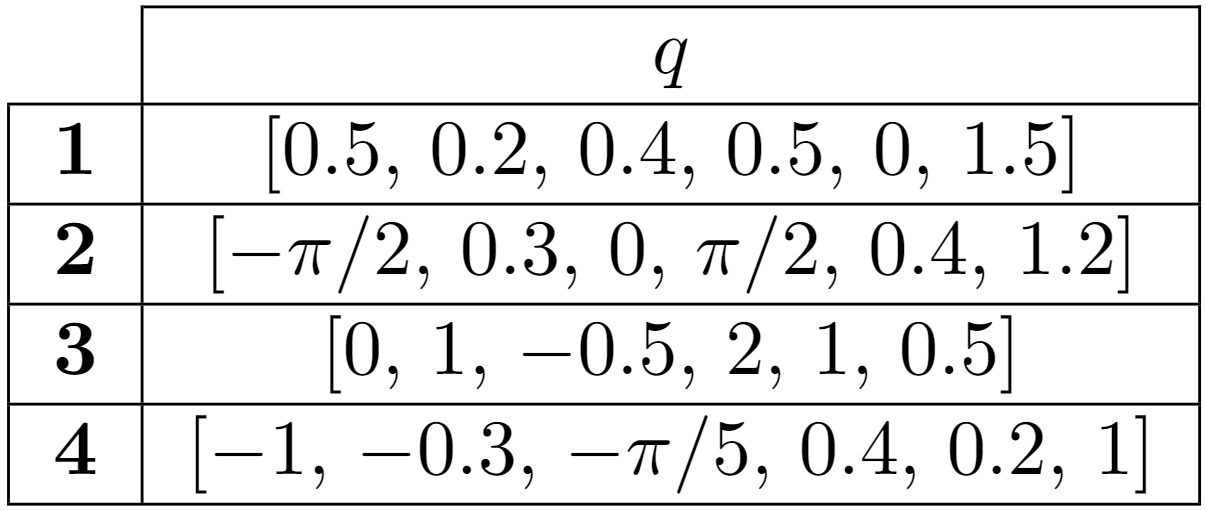

Se calcula la cinemática inversa del robot , en la primera configuración al ser una configuración singular fue necesario dar un parámetro de posición inicial de las articulaciones para llegar a las configuraciones esperadas:

q1 = Robot.ikunc(MTH_Robot1,[0.1 0.1 0.1 0 0 1])

q1 =     0.5000    0.2000    0.4000    0.5115   -0.0000    1.4885


q2 = Robot.ikunc(MTH_Robot2)

q2 =    -1.5708    0.3000   -0.0000    1.5708    0.4000    1.2000


q3 = Robot.ikunc(MTH_Robot3)

q3 =    -0.0000    1.0000   -0.5000    2.0000    1.0000    0.5000


q4 = Robot.ikunc(MTH_Robot4)

q4 =    -1.0000   -0.3000   -0.6283    0.4000    0.2000    1.0000


Implementando el algoritmo de cinemática inversa, teniendo en cuenta los parámetros de peso del error y posición inicial los cuales dan una semilla para iterar en las posibles configuraciones se realizó el cálculo de las configuraciones solicitadas. 

ik = inverseKinematics('RigidBodyTree',robotRST);
weights = [0.25 0.25 0.25 1 1 1];
c1 = num2cell([0.1 0.1 0.1 0 0 1]);
initialguess = homeConfiguration(robotRST);
[initialguess.JointPosition] = c1{:};
[configSoln,solnInfo] = ik('endeffector',double(MTH_Robot1),weights,initialguess);
configSoln

configSoln = 1×6 struct array with fields:
    JointName
    JointPosition


c1 = num2cell([-1 0.1 0 1 0.1 1]);
initialguess = homeConfiguration(robotRST);
[initialguess.JointPosition] = c1{:};
[configSoln,solnInfo] = ik('endeffector',double(MTH_Robot2),weights,initialguess);
configSoln

configSoln = 1×6 struct array with fields:
    JointName
    JointPosition


c1 = num2cell([0.1 0.1 0.1 0.1 0 1]);
initialguess = homeConfiguration(robotRST);
[initialguess.JointPosition] = c1{:};
[configSoln,solnInfo] = ik('endeffector',double(MTH_Robot3),weights,initialguess);
configSoln

configSoln = 1×6 struct array with fields:
    JointName
    JointPosition


c1 = num2cell([-0.1 0.1 0 0.1 0.1 1]);
initialguess = homeConfiguration(robotRST);
[initialguess.JointPosition] = c1{:};
[configSoln,solnInfo] = ik('endeffector',double(MTH_Robot4),weights,initialguess);
configSoln

configSoln = 1×6 struct array with fields:
    JointName
    JointPosition


En esta ocasion la naturaleza del problema de resolver la cinematica inversa puede tener diferentes soluciones e incluso dependiendo del algoritmo puede no tener solucion. Por ejemplo, el toolbox **perter corke** no fue capaz de resolver la posicion x2, mientras que el toolbox **RST** en todos los casos fue capaz de encontrar una de las 4 posibles soluciones y en el caso donde la solucion coincide con la configuracion de articulaciones dadas inicialmente, la exactitud fue mayor a la dada por el toolbox **Perter Corke.**

Acorde a las 4 posturas (x,y,z,roll,pitch,yaw)′ que se ecuentran dentro del espacio de trabajo mostradas en la tabla, se determina la configuracion del manipulador:

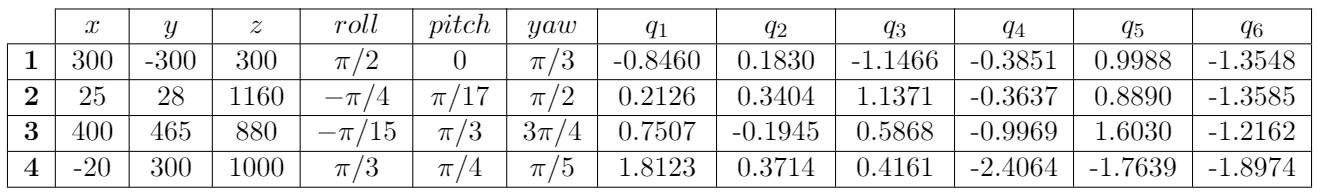

Primero se propone las siguientes posturas:

x1 = transl([300 -300 300])*rpy2tr(flip([pi/2 0 pi/3]),'zyx');
x2 = transl([25 28 1160])*rpy2tr(flip([-pi/4 pi/17 pi/2]),'zyx');
x3 = transl([400 465 880])*rpy2tr(flip([-pi/15 pi/3 3*pi/4]),'zyx');
x4 = transl([-20 300 1000])*rpy2tr(flip([pi/3 pi/4 pi/5]),'zyx');

Ahora usando el toolbox **RVC** se calcula la cinemática inversa:

s1 = Robot.ikunc(x1)

s1 =    -0.8450   -0.1830    1.1466   -0.3851   -0.9988   -1.3548


s2 = Robot.ikunc(x2)

s2 =     0.2126   -0.3404   -1.1371   -0.3637   -0.8890   -1.3585


s3 = Robot.ikunc(x3)

s3 =     0.7507    0.1945   -0.5868   -0.9969   -1.6030   -1.2162


s4 = Robot.ikunc(x4)

s4 =     1.8123   -0.3714   -0.4161   -2.4064    1.7939   -1.8974


Verificando las posturas propuestas por medio de la GUI desarrollada, se obtienen los siguientes resultados.

Sacando las cotas a detalle para el primer caso se comprueba el correcto funcionamiento de la GUI.